**Question 2: **

close all; % figure windows
clear all; % vars in workspace
clc; % clear command prompt

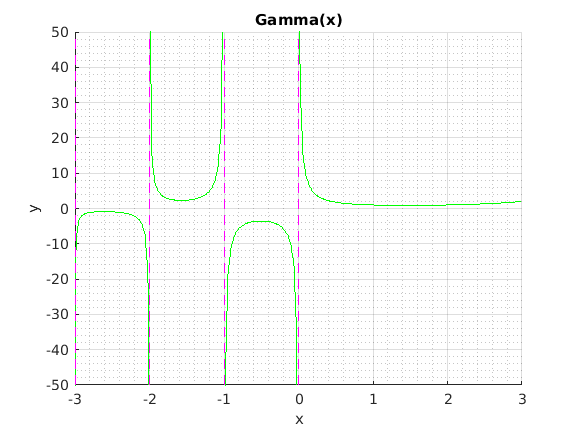

% construct vectors over (-3, 3] that DO NOT include
% the asymptotes at -3, -2, -1, 0
x1 = -2.999: 0.01 : -2.00001; 
x2 = -1.999: 0.01 : -1.00001; 
x3 = -0.999: 0.01 : -0.00001; 
x4 = 0.0001: 0.01 : 3; 

% Evaluate gamma at each vector
y1 = gamma(x1);
y2 = gamma(x2);
y3 = gamma(x3);
y4 = gamma(x4); 

% Plot paired points as green solid lines. 
figure(1)
clf;
hold on
grid on; grid minor
plot(x1, y1, 'g', x2, y2, 'g', x3, y3, 'g', x4, y4, 'g')

% Plot vertical lines at x = -3, -2, -1, and 0
plot([-3, -3], [-50, 50], 'm--') % line made of (-3, -50) and (-3, 50)
plot([-2 -2], [-50, 50], 'm--')
plot([-1 -1], [-50, 50], 'm--')
plot([0 0], [-50, 50], 'm--')

axis([-3 3 -50 50]) % xrange and yrange respectively. 

xlabel('x')
ylabel('y')
title('Gamma(x)')